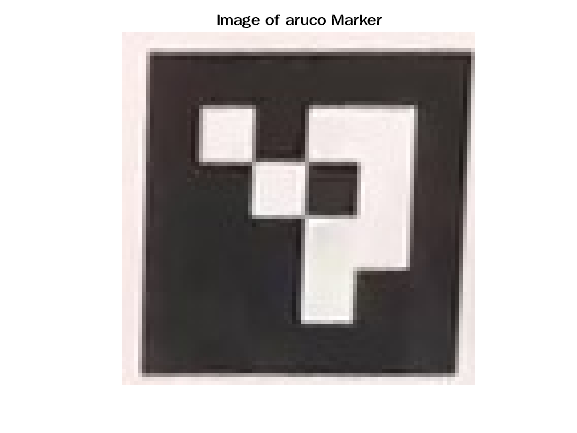


%Step 1: Read Images

arucoImage = imread('Frame0.jpg');
figure;
imshow(boxImage);
title('Image of aruco Marker');

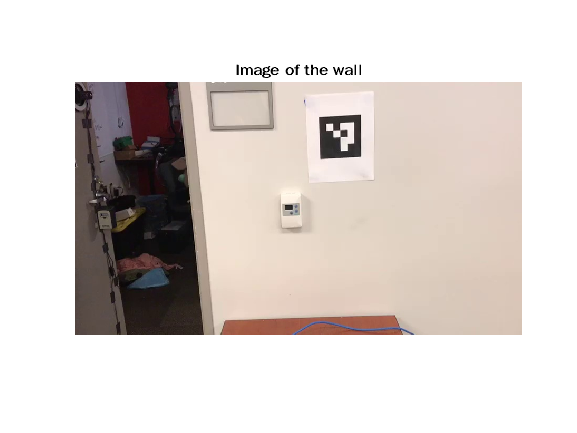


sceneImage = imread('Frame1.jpg');
figure;
imshow(sceneImage);
title('Image of the wall');


%Step 2: Detect Feature Points

arucoImageGS = rgb2gray(arucoImage)

arucoImageGS = 87×87 uint8 matrix
   238   244   242   237   238   240   239   239   241   241   242   241   240   240   241   242   240   240   240   240   240   241   241   240   243   242   241   240   239   240   241   242   242   243   243   242   241   240   240   240   242   242   243   242   240   240   242   244   241   241
   240   240   239   241   242   239   235   236   243   242   242   241   242   242   242   241   240   240   240   240   240   241   241   240   238   237   236   237   238   238   238   237   235   236   237   239   240   241   241   241   240   239   238   240   242   242   239   236   238   240
   242   238   239   243   243   239   240   246   245   243   242   242   243   243   240   238   243   242   242   242   242   242   241   241   242   241   240   240   241   241   239   237   238   238   238   238   239   239   238   237   241   241   240   241   242   241   239   237   243   244
   243   240   241   241   240   241   245   247   245   246   

sceneImageGS = rgb2gray(sceneImage)

sceneImageGS = 480×848 uint8 matrix
   111   114   116   119   119   113   114   124   114   113   116   113   100    70    76    86    94    85    85    89    88    93   104   111   117   118   116   113   115   111   110   107   101   111   114   108   107   114   114   114   113   113   113   114   114   114   114   114   113   112
   127   123   125   122   116   123   124   109   114   113   113   116   107    95    68    79    98    93    86    87    85    89   104   109   118   115   109   110   112   110   109   110   109   113   114   111   108   110   114   114   114   113   113   114   115   114   114   114   113   111
    94    88    65    59    84   104   109   116   113   113   115   112   114   122    87    72    87    92    86    86    86    88   103   106   108   109   109   111   113   112   110   110   116   115   111   112   108   109   116   112   114   113   113   114   115   114   114   114   112   111
    28    19    20    19    13    25    55    73   113   113 

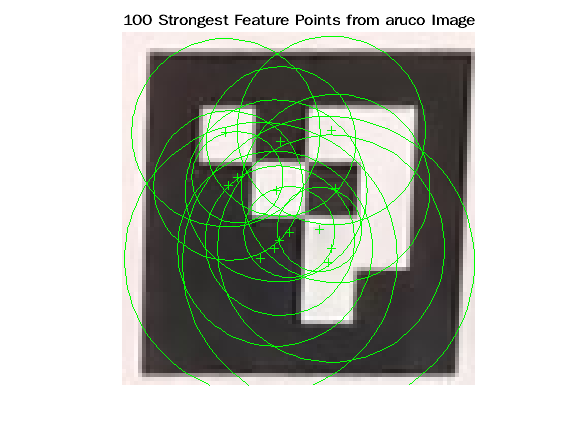


arucoPoints = detectSURFFeatures(arucoImageGS);
scenePoints = detectSURFFeatures(sceneImageGS);

figure;
imshow(arucoImage);
title('100 Strongest Feature Points from aruco Image');
hold on;
plot(selectStrongest(arucoPoints, 100));

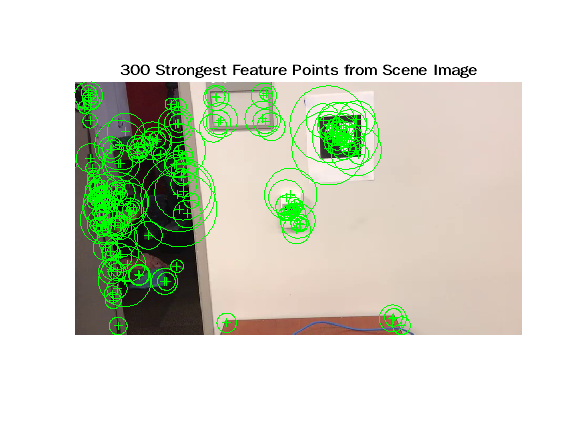


figure;
imshow(sceneImage);
title('300 Strongest Feature Points from Scene Image');
hold on;
plot(selectStrongest(scenePoints, 300));

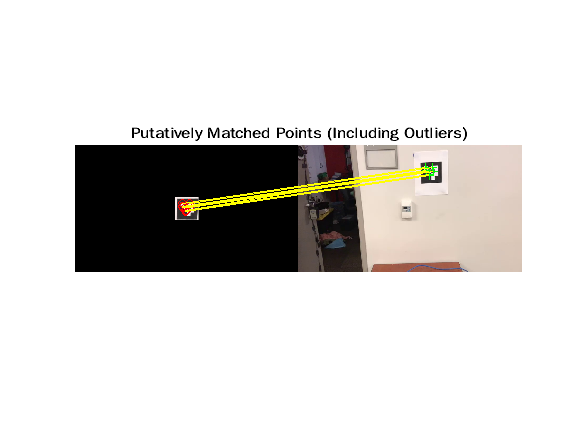


%Step 3: Extract Feature Descriptors

[arucoFeatures, arucoPoints] = extractFeatures(arucoImageGS, arucoPoints);
[sceneFeatures, scenePoints] = extractFeatures(sceneImageGS, scenePoints);

%Step 4: Find Putative Point Matches

arucoPairs = matchFeatures(arucoFeatures, sceneFeatures);

matchedarucoPoints = arucoPoints(arucoPairs(:, 1), :);
matchedScenePoints = scenePoints(arucoPairs(:, 2), :);
figure;
showMatchedFeatures(arucoImage, sceneImage, matchedarucoPoints, ...
    matchedScenePoints, 'montage');
title('Putatively Matched Points (Including Outliers)');

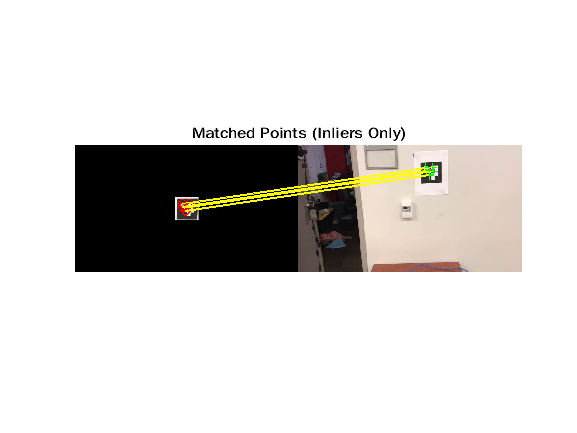


%Step 5: Locate the Object in the Scene Using Putative Matches

[tform, inlierIdx] = ...
    estimateGeometricTransform2D(matchedarucoPoints, matchedScenePoints, 'affine');
inlierarucoPoints   = matchedarucoPoints(inlierIdx, :);
inlierScenePoints = matchedScenePoints(inlierIdx, :);

figure;
showMatchedFeatures(arucoImage, sceneImage, inlierarucoPoints, ...
    inlierScenePoints, 'montage');
title('Matched Points (Inliers Only)');

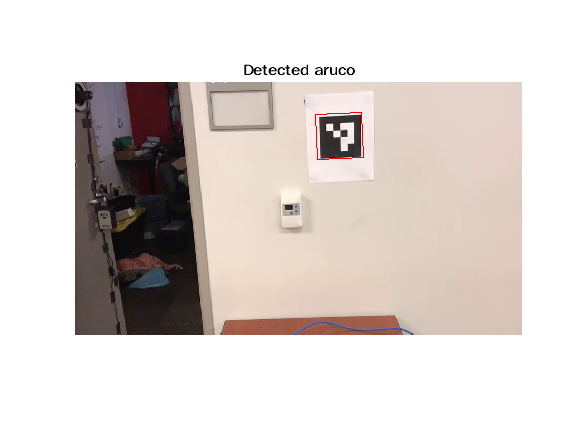


arucoPolygon = [1, 1; size(arucoImage, 2), 1;size(arucoImage, 2), size(arucoImage, 1);1, size(arucoImage, 1); 1, 1];                   

newarucoPolygon = transformPointsForward(tform, arucoPolygon);

figure;
imshow(sceneImage);
hold on;
line(newarucoPolygon(:, 1), newarucoPolygon(:, 2), 'Color', 'r');
title('Detected aruco');

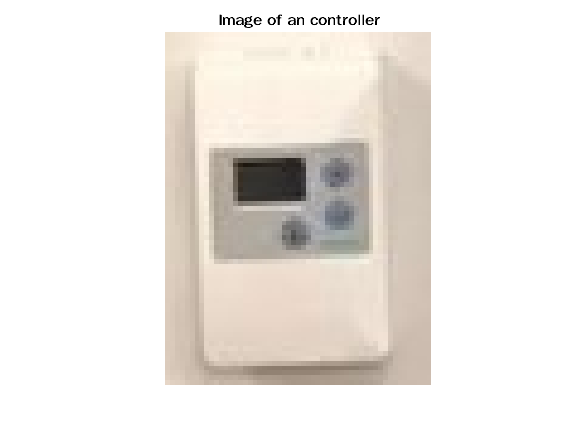


%Step 7: Detect Another Object

controllerImage = imread('Frame3.jpg');
figure;
imshow(controllerImage);
title('Image of an controller');


controllerImageGS = rgb2gray(controllerImage)

controllerImageGS = 73×55 uint8 matrix
   226   228   230   231   232   234   236   238   239   241   243   244   245   244   244   244   244   244   244   245   245   245   245   245   242   245   246   243   242   243   245   246   245   246   241   245   241   246   242   244   242   239   233   235   233   231   233   226   226   225
   227   228   229   230   232   234   236   238   242   243   245   246   246   246   246   246   246   246   246   246   246   246   246   246   247   245   244   245   247   248   247   246   243   244   242   244   242   244   243   243   244   240   234   236   234   231   232   224   230   227
   227   228   229   230   232   234   236   238   240   241   243   244   244   244   244   245   246   246   246   246   246   245   245   245   246   244   244   246   246   244   245   247   239   241   244   244   245   243   245   245   246   243   236   237   234   231   233   226   228   226
   228   228   230   232   233   234   237   240   240   2

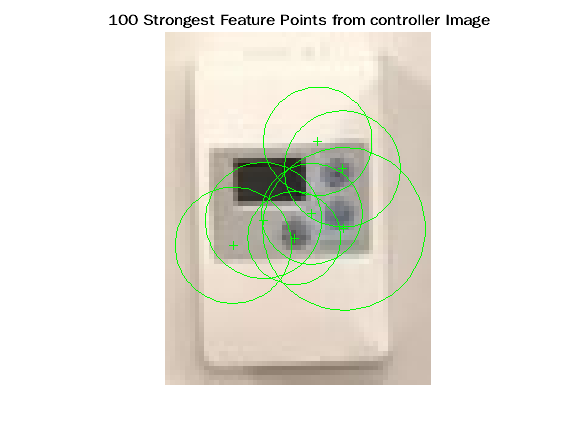

controllerPoints = detectSURFFeatures(controllerImageGS);

figure;
imshow(controllerImage);
hold on;
plot(selectStrongest(controllerPoints, 100));
title('100 Strongest Feature Points from controller Image');

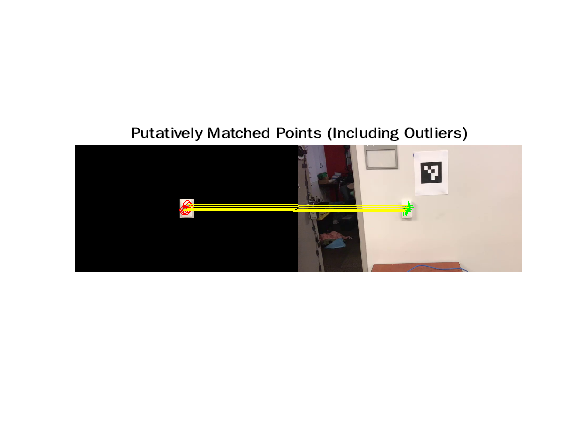


[controllerFeatures, controllerPoints] = extractFeatures(controllerImageGS, controllerPoints);

controllerPairs = matchFeatures(controllerFeatures, sceneFeatures, 'MaxRatio', 0.9);

matchedcontrollerPoints = controllerPoints(controllerPairs(:, 1), :);
matchedScenePoints = scenePoints(controllerPairs(:, 2), :);
figure;
showMatchedFeatures(controllerImage, sceneImage, matchedcontrollerPoints, ...
    matchedScenePoints, 'montage');
title('Putatively Matched Points (Including Outliers)');

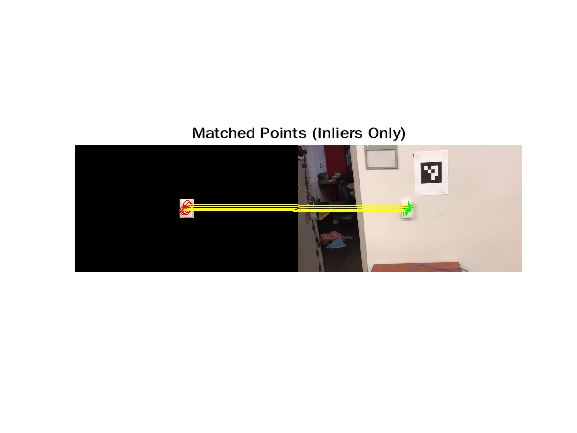


[tform, inliercontrollerPoints, inlierScenePoints] = ...
    estimateGeometricTransform(matchedcontrollerPoints, matchedScenePoints, 'affine');
figure;
showMatchedFeatures(controllerImage, sceneImage, inliercontrollerPoints, ...
    inlierScenePoints, 'montage');
title('Matched Points (Inliers Only)');

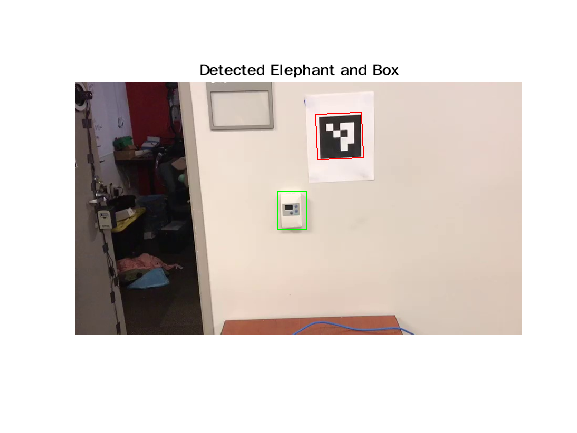


controllerPolygon = [1, 1;...                                 % top-left
        size(controllerImage, 2), 1;...                       % top-right
        size(controllerImage, 2), size(controllerImage, 1);...  % bottom-right
        1, size(controllerImage, 1);...                       % bottom-left
        1,1];                         % top-left again to close the polygon

newcontrollerPolygon = transformPointsForward(tform, controllerPolygon);

figure;
imshow(sceneImage);
hold on;
line(newarucoPolygon(:, 1), newarucoPolygon(:, 2), 'Color', 'r');
line(newcontrollerPolygon(:, 1), newcontrollerPolygon(:, 2), 'Color', 'g');
title('Detected Elephant and Box');